# Estimating `k` and $\tau$

% TODO: Controllare Mixer 
% TODO: Tau = 0
% TODO: Confronto Hinf
% K = 1:15

load 'quad_copter_models.mat';

InnerReferenceModel = mk_2nd_order(12, .6);
InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);
PitchRateModel_dt = c2d(PitchRateModel, Ts);

We now use VRFT to generate a controller for every combination of `k` and $\tau
$ which we will use to  evaluate the closed loop step response.

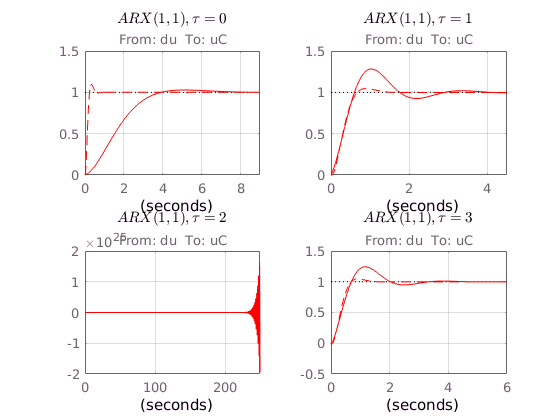

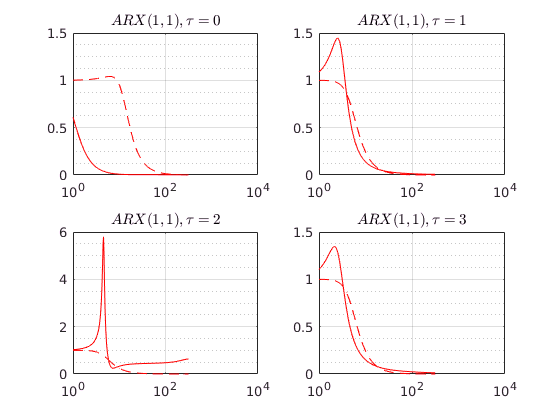

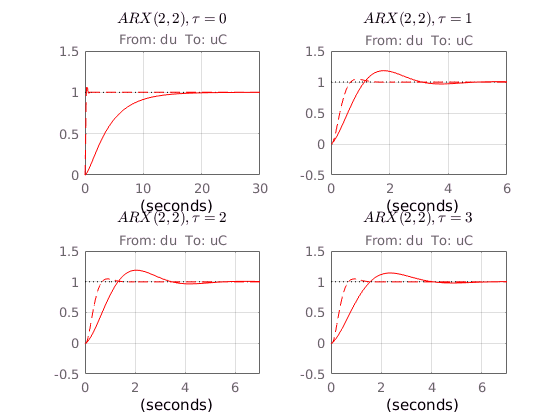

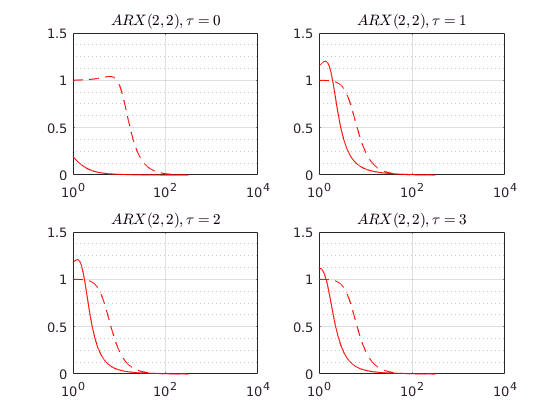

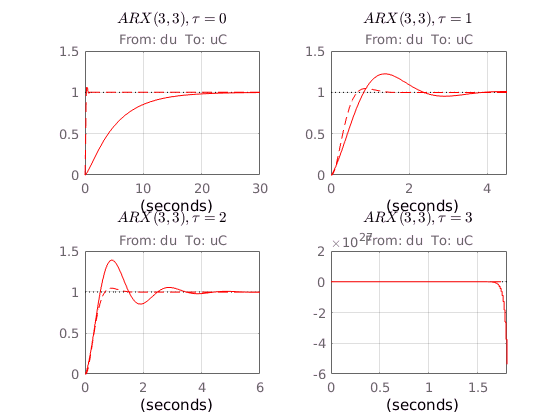

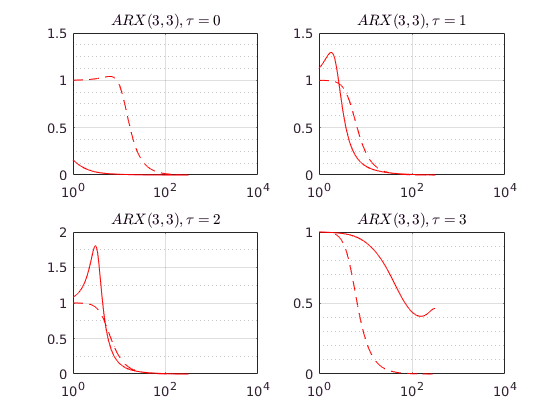

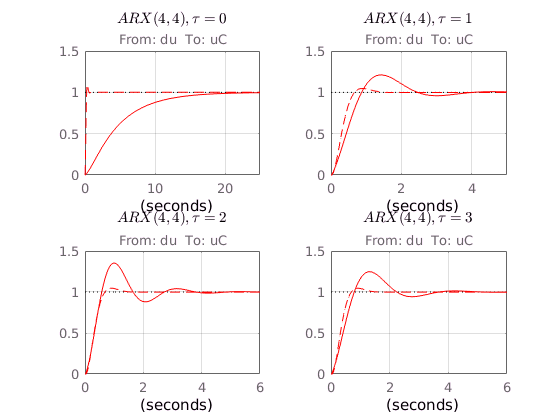

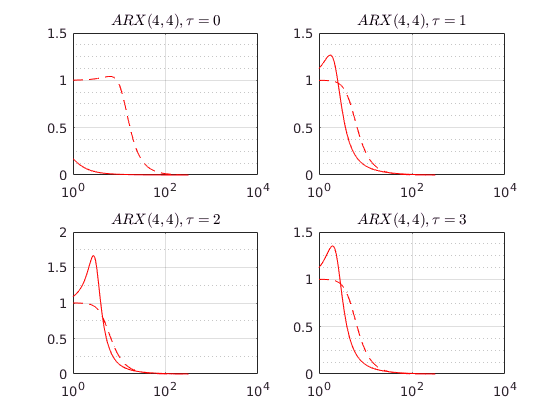

% we consider ARX models of orders 1 to 25 and delays from 0 to 4 steps inclusive. 

bode_bw = { 10E-1, 10E3 };

for k = 1:10
    for tau = 1:1
        z = tf('z', Ts);
        InnerReferenceModels{k, tau} = InnerReferenceModel_dt * (1 / z^(tau-1));
       
        InnerControllers{k, tau} = VRFT1_ry(vrft_data.dM, vrft_data.q_dot, ...
            InnerReferenceModels{k, tau}, PIDControllerClass_dt, [], k, []);
        
        % cloop = loopsens(PlantModel_dt, InnerControllers{k, tau});
        cloop = loopsens(PitchRateModel_dt, InnerControllers{k, tau});
        InnerLoop_VRFTs{k, tau} = cloop.Ti;

        [mag, ~, wout] = bode(InnerReferenceModels{k, tau}, bode_bw);
        InnerRefMag{k, tau} = squeeze(mag);
        InnerRefWout{k, tau} = squeeze(wout);
        
        [mag, ~, wout] = bode(InnerLoop_VRFTs{k, tau}, bode_bw);
        InnerLoopMag{k, tau} = squeeze(mag); 
        InnerLoopWout{k, tau} = squeeze(wout);
   end
   
   figure()
       ax11 = subplot(2, 2, 1);            
           step(InnerReferenceModels{k, 1}, 'r--', InnerLoop_VRFTs{k, 1}, 'r'); grid on;
           title({sprintf('$ARX(%i, %i), \\tau = 0$', k, k)}, 'Interpreter', 'latex');
           xlabel(' '); ylabel(' '); 
           
       ax12 = subplot(2, 2, 2);            
           step(InnerReferenceModels{k, 2}, 'r--', InnerLoop_VRFTs{k, 2}, 'r'); grid on;
           title({sprintf('$ARX(%i, %i), \\tau = 1$', k, k)}, 'Interpreter', 'latex');
           xlabel(' '); ylabel(' ');
           
       ax21 = subplot(2, 2, 3);            
           step(InnerReferenceModels{k, 3}, 'r--', InnerLoop_VRFTs{k, 3}, 'r'); grid on;
           title({sprintf('$ARX(%i, %i), \\tau = 2$', k, k)}, 'Interpreter', 'latex');
           xlabel(' '); ylabel(' ');
           
       ax22 = subplot(2, 2, 4);            
           step(InnerReferenceModels{k, 4}, 'r--', InnerLoop_VRFTs{k, 4}, 'r'); grid on;
           title({sprintf('$ARX(%i, %i), \\tau = 3$', k, k)}, 'Interpreter', 'latex');
           xlabel(' '); ylabel(' ');
   
    figure()
        ax11 = subplot(2, 2, 1); 
            semilogx(InnerRefWout{k, 1}, InnerRefMag{k, 1}, 'r--', ...
                     InnerLoopWout{k, 1}, InnerLoopMag{k, 1}, 'r');
            grid minor;
            title({sprintf('$ARX(%i, %i), \\tau = %i$', k, k , 0)}, 'Interpreter', 'latex');
        
        ax12 = subplot(2, 2, 2); 
            semilogx(InnerRefWout{k, 2}, InnerRefMag{k, 2}, 'r--', ...
                     InnerLoopWout{k, 2}, InnerLoopMag{k, 2}, 'r');
            grid minor;
            title({sprintf('$ARX(%i, %i), \\tau = %i$', k, k , 1)}, 'Interpreter', 'latex');
        
        ax21 = subplot(2, 2, 3);
            semilogx(InnerRefWout{k, 3}, InnerRefMag{k, 3}, 'r--', ...
                     InnerLoopWout{k, 3}, InnerLoopMag{k, 3}, 'r');
            grid minor;
            title({sprintf('$ARX(%i, %i), \\tau = %i$', k, k , 2)}, 'Interpreter', 'latex');
        
        ax22 = subplot(2, 2, 4);
            semilogx(InnerRefWout{k, 4}, InnerRefMag{k, 4}, 'r--', ...
                     InnerLoopWout{k, 4}, InnerLoopMag{k, 4}, 'r');
            grid minor;
            title({sprintf('$ARX(%i, %i), \\tau = %i$', k, k , 3)}, 'Interpreter', 'latex');          
            
%     figure() 
%         pzmap(InnerControllers{k, 1}, InnerControllers{k, 2}, ...
%               InnerControllers{k, 3}, InnerControllers{k, 4});
%         legend({'$\tau = 0$', '$\tau = 1$', '$\tau = 2$','$\tau = 3$'}, ...
%             'Interpreter', 'latex', 'location', 'SouthWest');
%         title(sprintf('P/Z Map for the controller, k = %i', k)); 
%         
%     figure() 
%         pzmap(InnerLoop_VRFTs{k, 1}, InnerLoop_VRFTs{k, 2}, ...
%               InnerLoop_VRFTs{k, 3}, InnerLoop_VRFTs{k, 4});
%         legend({'$\tau = 0$', '$\tau = 1$', '$\tau = 2$','$\tau = 3$'}, ...
%             'Interpreter', 'latex');
%         title(sprintf('P/Z Map for the Inner Loop with the Controller, k = %i', k));         
end

Finally we can take a look a the results:

The dotted line in the Bode plots is the reference model. The continuous line is the actual model. 

... Nothing works ... 